# Chapter 7 - Some Optimization Problems Solved w/ Matlab

## Section 2 - Solving Quadratic Optimal Control Problems w Matlab

clear all; clc

**Notes: **

Advantages over pole-placement: 

- Provides a systematic way to compute the state feedback control gain matrix

- System design is always stable. 

System equation: $\overset{\cdot }{x} =Ax+Bu$ is used to determine the matrix K of the optimal control vector: $u\left(t\right)=−Kx\left(t\right)$, so as to minimize the performance index, $J=\text{ }\int_0^{\infty } \left(x∗Qx+u∗Ru\right)dt$, where Q and R are positive-definitie Hermitian matrices. See the rest of the derivation on pg 397-398. 

Steps to solving for the Optimal Matrix, K, using *Reduced-matrix Riccati equation* :

- Solve the reduced-matrix Riccati equation [ $A^∗ P+PA−{PBR}^{−1} B^∗ P+Q=0$]  for the matrix P. If a positive-definite matrix P exists, then the system is stable/ matrix [A - BK] is stable. 

- Substitute matrix P into $K=T^{−1} {\left(T^∗ \right)}^{−1} B^∗ P=R^{−1} B^∗ P$ to determine the optimal matrix, K.

## 7-6 Determine the optimal feedback gain matrix K such that the performance index is minimized.

% Define plant
A = [0 1; 0 0];
B = [0; 1];

% Define Q = [1 0; 0 u] , where u > 0
% Solve Riccati eq: A*P + PA - PBR^-1 B*P + Q = 0 for P and u

% Determine K based on K = R^-1B*P
% The optimal Control signal is u = -Kx = -x1 - sqrt(u + 2)*x2

Error using lqr (line 43)
The "lqr" command failed to stabilize the plant or find an optimal feedback gain. To remedy this problem:
1. Make sure that all unstable poles of A are controllable through B (use MINREAL to check)
2. Modify the weights Q and R to make [Q N;N' R] positive definite (use EIG to check positivity).

## 7-7 Solving quadratic optimal regulator problems with 'lqr' function

clear all; clc

'lqr' solves the continuous- time, linear, quadratic regulator problem and the associated Riccati equation. This command calculates the optimal feedback gain matrix K, such that the feedback control law $u=−Kx$ minimizes the performance index J. 

% Define plant
A = [-1 1; 0 2]; 
B = [1; 0];

% Define the positive-defininite Hernitian matrices Q and R
Q = [1 0; 0 1];
R = [1];

K = lqr(A, B, Q, R)

This system cannot be stabilized by the state-feedback control scheme no matter the matrix K chosen because the system is not state controllable.

## 7-8 Design a quadratic optimal regulator system using lqr

clear all; clc

K =     0.0143    0.1107    0.0676


P =     4.2625    2.4957    0.0143
    2.4957    2.8150    0.1107
    0.0143    0.1107    0.0676


E =   -5.0958 + 0.0000i
  -1.9859 + 1.7110i
  -1.9859 - 1.7110i


Determine the positive-definite solution matrix, P, of the Riccati equation, the optimal feedback gain matrix, K, and the eigenvalues of matrix [A - BK]

% Define plant
A = [0 1 0; 0 0 1; -35 -27 -9];
B = [0; 0; 1];

%Q and R weights
Q = [1 0 0; 0 1 0; 0 0 1];
R = [1];

% Determine K, P, and E (eigenvalue vector --> gives closed-loop poles of A-BK)
[K, P, E] = lqr(A, B, Q, R)

Next, obtain the response, x, of the regulator system to the initial condition given 

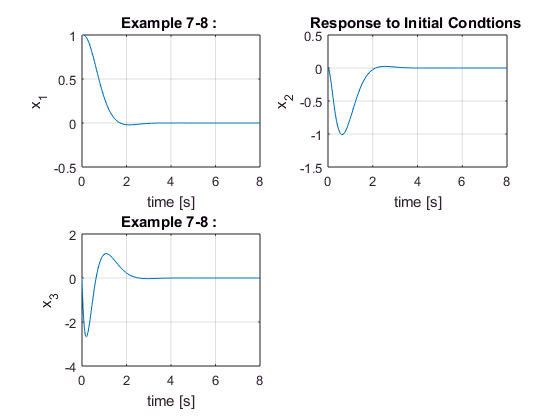

% Define system 
sys = ss(A-B*K, eye(3), eye(3), eye(3));

% Response to initial conditions
t = 0:0.01:8;
x = initial(sys, [1;0;0], t);

x2 = eye(3)*x';

% Plot
figure;
subplot(221); plot(t, x2(1,:)), grid
title('Example 7-8 : '), xlabel('time [s]'), ylabel('x_1')
subplot(222); plot(t, x2(2,:)), grid
title('Response to Initial Condtions '), xlabel('time [s]'), ylabel('x_2')
subplot(223); plot(t, x2(3,:)), grid
title('Example 7-8 : '), xlabel('time [s]'), ylabel('x_3')

## 7-9 Use LQR to determine the optimal state-feedback matrix K

clear all; clc

% Define plant
A = [ 0 1 0; 0 0 1; 0 -2 -3];

K =   100.0000   53.1200   11.6711


B = [0; 0; 1];
C = [1 0 0];
D = 0;

% Define Q and R
% To get a fast response, q11 must be sufficiently large compared
% to q22, q33, and r1. 
Q = [100 0 0; 0 1 0; 0 0 1];
R = [0.01];

K = lqr(A, B, Q, R)

k1 = K(1);
k2 = K(2);
k3 = K(3);

Next, use the matrix, K, to investigate the step-response characteristics of the design system. 

Define the state matrix, control matrix, output matrix, and direct transmission matrix of the designed systems as AA, BB, CC, And DD

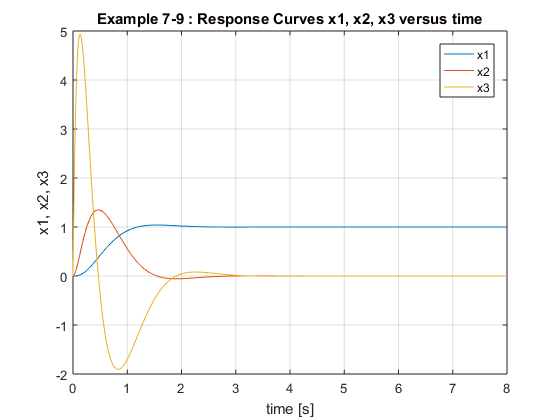

AA = A-B*K;
BB = B*k1;
CC = C;
DD = D;


%Step response
t = 0:0.01:8;
[y, x, t] = step(AA, BB, CC, DD, 1, t);

%Plot
figure; plot(t, x), grid
title('Example 7-9 : Response Curves x1, x2, x3 versus time')
xlabel('time [s]'), ylabel('x1, x2, x3')
legend('x1', 'x2', 'x3')